**1. **La funcion principal tiene como nombre "`Proyecto_final_4(k, n, secret)`" la funcion recibe tres parametros 

-  **k**: El número mínimo de fragmentos necesarios para recontruir el secreto.

- **n**: El número total de fragmentos generados.

- `secret`: El valor del secreto que deseas compartir.

Parametro k:4
Parametro n:10
Secreto Original: 1234
Fragmentos Generados:
           1        2886
           2        6066
           3       10990
           4       17874
           5       26934
           6       38386
           7       52446
           8       69330
           9       89254
          10      112434

El polinomio generado es: p(x) = 1234.00 +960.00 * x^1 +656.00 * x^2 +36.00 * x^3


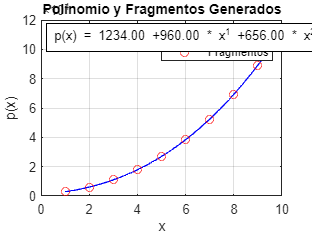

Fragmentos Seleccionados:
          10      112434
           8       69330
           6       38386
           4       17874

Secreto Recuperado: 1234


Proyecto_final_4(4,10,1234)

Parametro k:3
Parametro n:6
Secreto Original: 1234
Fragmentos Generados:
           1        1973
           2        2776
           3        3643
           4        4574
           5        5569
           6        6628

El polinomio generado es: p(x) = 1234.00 +707.00 * x^1 +32.00 * x^2
Fragmentos Seleccionados:
           5        5569
           2        2776
           1        1973

Secreto Recuperado: 1234


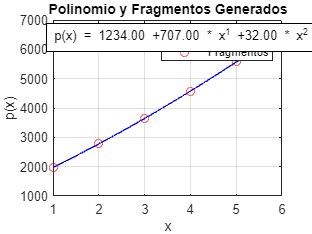

Proyecto_final_4(3,6,1234)

**Responsabilidades**:

- Imprime el secreto original.

- Llama a `generate_shares` para dividir el secreto en fragmentos.

- Muestra los fragmentos generados.

- Llama a `visualize_polynomial` para graficar el polinomio y los fragmentos.

- Llama a `reconstruct_secret` para reconstruir el secreto a partir de los fragmentos seleccionados.

- Imprime el secreto recuperado.

**2. **`generate_shares(k, n, secret)`

Esta función **genera los fragmentos** a partir del secreto utilizando un polinomio aleatorio de grado k−1k-1k−1.

- **Salida**:

- `shares`: Una matriz donde cada fila contiene un punto (x, p(x)) del polinomio.

- `coefficients`: Los coeficientes del polinomio generado, donde el término constante es el secreto.

- **Funcionamiento**:

- Genera un polinomio con coeficientes aleatorios, siendo el primer coeficiente el secreto.

- Evalúa este polinomio en los puntos `x = 1, 2, ..., n` para obtener los fragmentos.

**3. **`visualize_polynomial(coefficients, shares, n)`

Esta función **grafica el polinomio** y los fragmentos generados.

- **Parámetros**:

- `coefficients`: Los coeficientes del polinomio generado.

- `shares`: Los puntos (x, p(x)) generados.

- `n`: El número total de fragmentos.

- **Funcionamiento**:

- Define la función polinómica con los coeficientes generados.

- Genera valores de x entre 1 y `n` para graficar el polinomio.

- Grafica la curva del polinomio y superpone los fragmentos generados.

**4. **`reconstruct_secret(shares, k)`

Esta función **reconstruye el secreto** usando los fragmentos seleccionados.

- **Salida**: 

- `recovered_secret`: El valor del secreto reconstruido.

- **Funcionamiento**:

- Selecciona aleatoriamente kkk fragmentos de la lista generada.

- Llama a `lagrange_interpolation` para realizar la interpolación polinómica y reconstruir el secreto.

**5. **`lagrange_interpolation(x, y, x_eval)`

Es la implementación de la **interpolación de Lagrange** para reconstruir el polinomio.

- **Parámetros**:

- `x`: Coordenadas x de los fragmentos seleccionados.

- `y`: Valores de p(x) de los fragmentos seleccionados.

- `x_eval`: El punto donde se evalúa el polinomio reconstruido (en este caso, x=0x = 0x=0).

- **Salida**:

- `result`: El valor del polinomio en `x_eval` (es decir, el secreto reconstruido).

- **Funcionamiento**:

- Calcula los polinomios de base de Lagrange  para cada fragmento.

- Suma los valores ponderados para obtener el polinomio reconstruido.

- Evalúa el polinomio en x=0 para recuperar el secreto.